# Perception Basic Process Live Notebook

## Getting Add-Ons

Please make sure you have the following toolboxes installed before you proceed:

- [**Computer Vision Toolbox** ](https://www.mathworks.com/add-ons/VP/?s_tid=srchtitle)

- [**Statistics and Machine Learning Toolbox**](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'ST', 'focused', 'pca');)**.**

## Getting the Files

There will be two steps to download necessary files: (1) Regular files via GIT as usual and (2) Large Neural Net Yolo file downloaded from the internet.

### (1) GIT Files

Fetch and Merge the latest files from GIT.

You should see a folder structure as the one below. Make **vision_tutorials **the top folder in your matlab path:

**vision_tutorials  <-- make this top folder in path**

  |__ pt_clouds

          |__ detectors

          |__ helper_files

          |__ 09_perception_basics.mlx

          |__ 10_accessing_imgs_ptClouds.mlx

### (2) Detector Files

Download directly from this --> [**link**](https://lipscomb.instructure.com/users/55882/files/4803628/download?download_frd=1) <-- and place the detector file in the **ros_matlab/vision_tutorials/detectors **folder. 

File size ~230MB.

### *Add to Matlab Path

Note that vision_tutorials is a new folder with sub-folders inside of it. 

Please add it to your Matlab path.

## Overview

The general process: 

- Requires a RGB image and a point cloud taken from the same position

- Uses a pre-trained YOLO network to identify objects from the raw RGB image

- Pre-process the point cloud (downsample and extract the non-plane)

- Uses the YOLO output bounding boxes to extract objects from the point cloud

- Estimates the objects pose

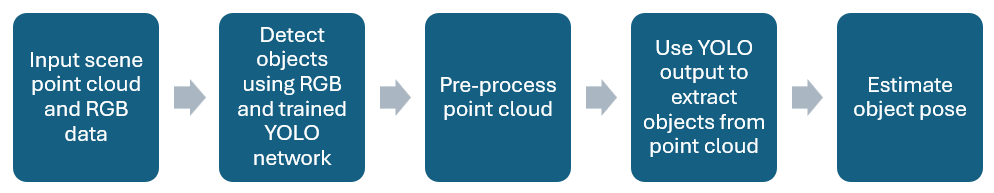

## Key Functions

### Yolo

- [detect()](https://www.mathworks.com/help/vision/ref/yolov2objectdetector.detect.html)

- [insertObjectAnnotation()](https://www.mathworks.com/help/vision/ref/insertobjectannotation.html)

### Point Clouds

- [pcshow()](https://www.mathworks.com/help/vision/ref/pcshow.html?searchHighlight=pcshow&s_tid=srchtitle_support_results_1_pcshow) 

- [pcfitPlane()](https://www.mathworks.com/help/vision/ref/pcfitplane.html) 

- [select()](https://www.mathworks.com/help/vision/ref/pointcloud.select.html)

- findObjectPoses -- locally defined.

#### Read sample point cloud and sample RGB data 

The point cloud and the raw image collected need to be taken from the same position.

Load the example `rgbImage` and example `ptCloud` found in the pt_clouds/helper_files folder 

load("./pt_clouds/helper_files/example_ptCloud_and_image.mat");

The image is a top-down view of objects on a table. There are cans, bottles, and pouches (the cyan-colored squares) in the image. It looks like the picture below.

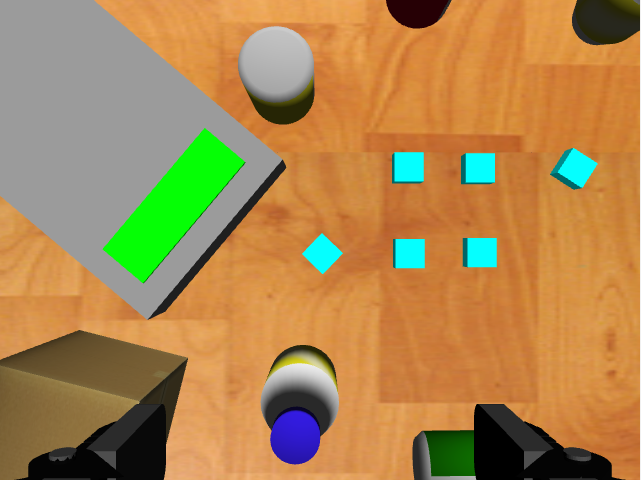

Display the image in your own system:

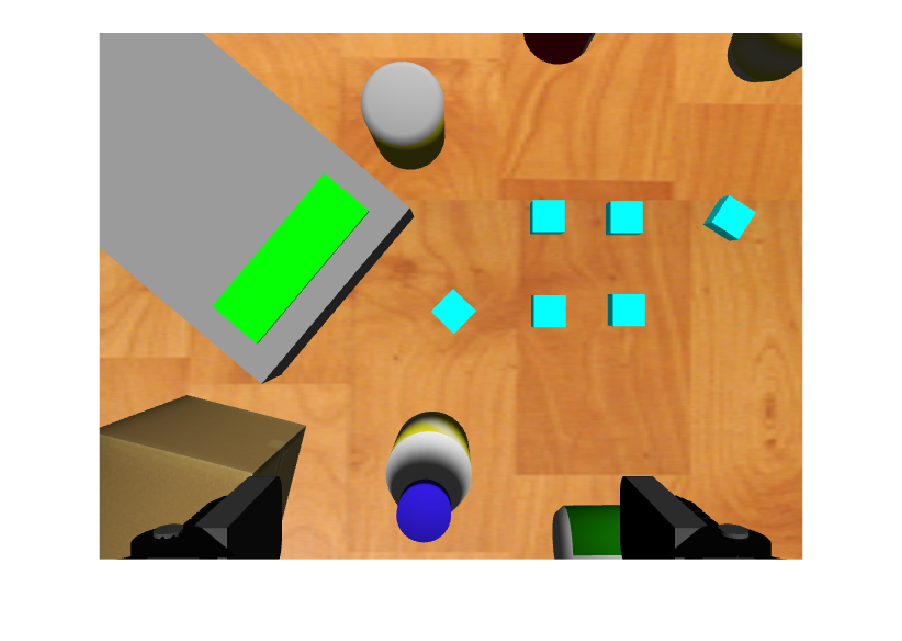

figure, imshow(rgbImage)

#### Detect objects using trained YOLO network

In order to identify objects, we need to apply a trained YOLO network to the image. 

Load pre-trained network (it will take several seconds):

pretrained = load("./detectors/detector_gral_sim.mat"); 
trainedYoloNet = pretrained.detector; % specifically accessing the detector

Compute bounding boxes using loaded detector

[bboxes,scores,labels] = detect(trainedYoloNet,rgbImage,Threshold=0.7);
numObjects = size(bboxes,1);

- `bboxes:` P-by-4 array defining P bounding boxes. Each row of `bboxes` contains a four-element vector, [x, y, width, height]. This vector specifies the upper-left corner and size of a bounding box in pixels. 

- `scores:` confidence scores for each bounding box (P-by-1)

- `labels:` labels assigned to the bounding boxes (P-by-1)

Specifically notice the `threshold` parameter input of the `detect` function. This `threshold` takes any objects detected whose `scores`** are lower than the specified **`threshold` and does not include them in the outputs.

#### **Visualize bounding boxes on raw RGB data**

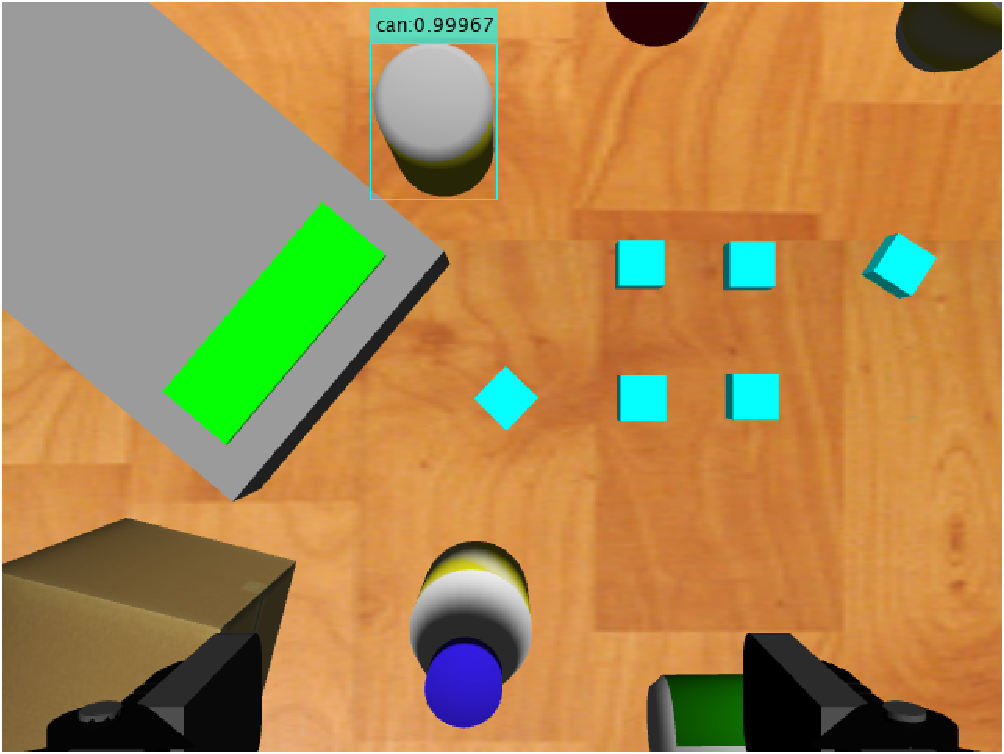

Visualize the computed bounding box with the raw RGB input data on your own system. The result should look similar to the picture above.

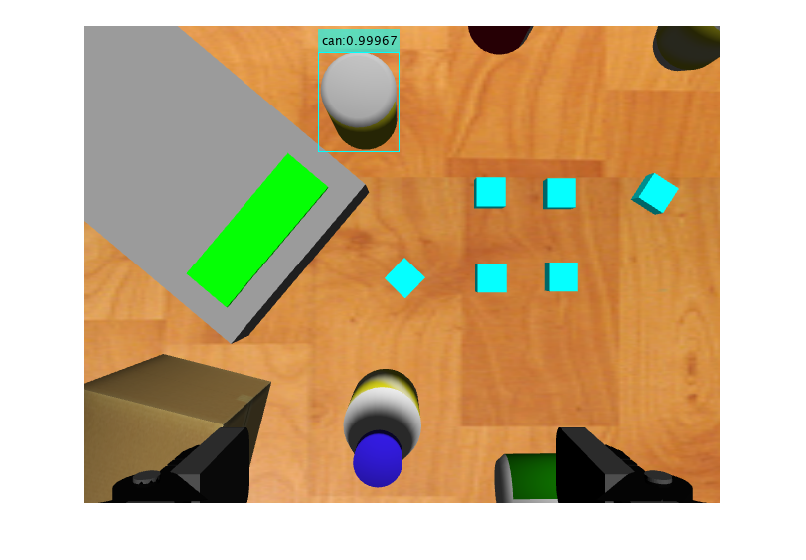

annotatedImage = insertObjectAnnotation(im2uint8(rgbImage), ...
                                        'Rectangle',...
                                        bboxes,...
                                        string(labels)+":"+string(scores),...
                                        'Color','cyan');
figure, imshow(annotatedImage);

#### Detect the plane and remove the plane from the point cloud

Our current point cloud looks like the picture below.

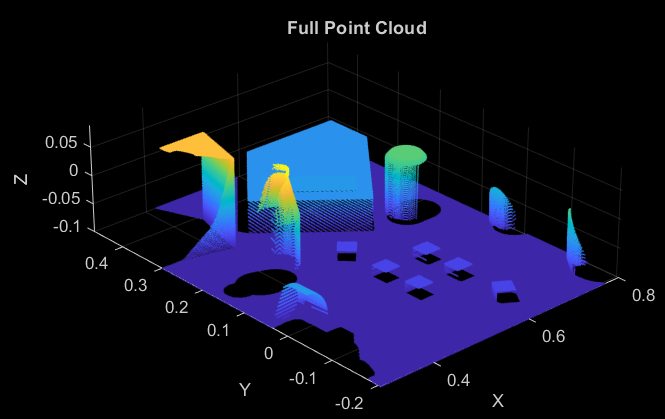

Plot the raw point cloud data

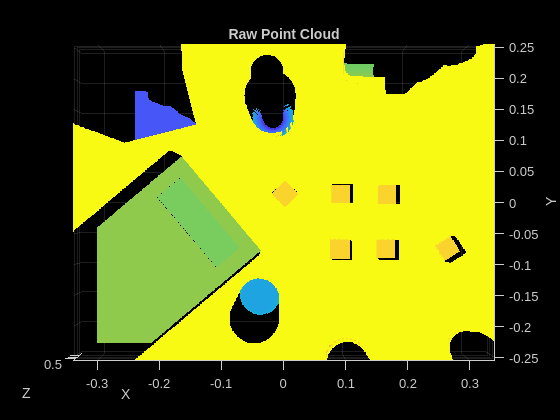

figure, pcshow(ptCloud,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("Raw Point Cloud");

Remove the plane from the raw point cloud data for further computation. (In our case the "plane" is the table the objects are on. We want to isolate the objects from the table.)

To do so, first identify the point clouds associated with a plane defined by the z-vec [ 0 0 1]. We will use **pcfitplane**() which will produce a plane equation 

ax + by + cz + d = 0.

Given this plane, each point in the point cloud can be associated with the plane or not. The points indeces will be stored in two variables planeIdx and nonPlaneIdx.

planeThickness = .001;       % metres
normalVector = [0,0,1];      % z-axis  
maxPlaneTilt = 5;            % Degrees

% Compute model of the plane (param associated with 4 coeffs ax + by + cz + d = 0)
[param, planeIdx, nonPlaneIdx] = pcfitplane(ptCloud, planeThickness, normalVector, maxPlaneTilt);

Now we can extract the desired points in the point cloud via select and pass the vector of indeces. Below we separate plane and nonPlane points:

% Assign to variables, which points belong to the plane and which do not
plane = select(ptCloud, planeIdx);
nonPlane = select(ptCloud, nonPlaneIdx);

Plane and nonPlane points can be visualized via pcShow:

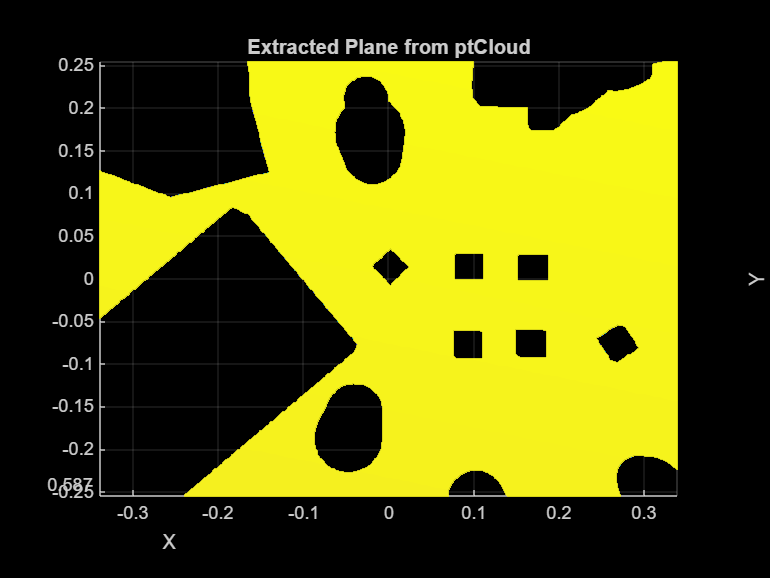

% Show the plane
figure, pcshow(plane,'ViewPlane','XY');axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("Extracted Plane from ptCloud");

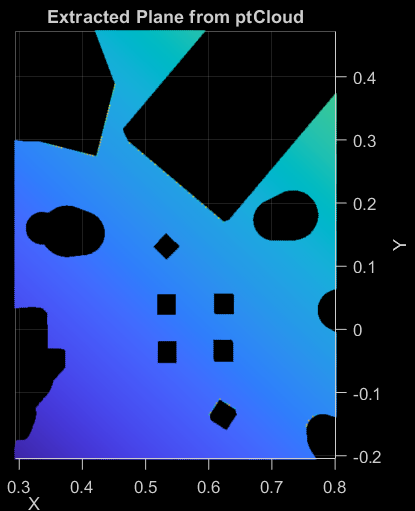

Show the objects (i.e. the nonPlane). 

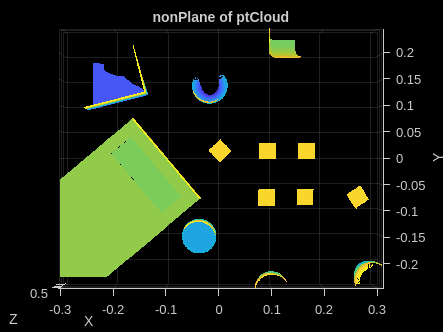

% show items
figure,pcshow(nonPlane,'ViewPlane','XY');axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("nonPlane of ptCloud");

Note that you can manipulate the view to see the 3D scene:

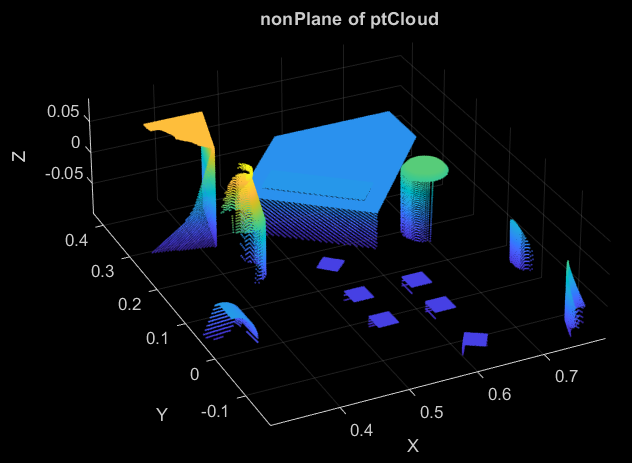

**nonPlane Mask**

The nonPlace mask is simply a vector, the length of all point clouds, that has a value of 1 for every index representing a point cloud where you have an object (no plane). These are the points we care about.

% non-plane mask 
[m,n,~] = size(rgbImage);

% Create a matrix the same size as the raw image and point cloud
nonPlaneMask = zeros(m,n);      

% Flatten the matrix into a column vector
nonPlaneMask = nonPlaneMask(:); 

% Set a value of 1 for all indeces in which there is an object. 
nonPlaneMask(nonPlaneIdx)= 1;

## Estimate object poses (findObjectPoses) wrt to the Camera Link

This section estimates the object poses wrt to the camera (not the robot base -- we will learn that in the next notebook) using the bounding box from yolo and the pre-processed point cloud data. 

- If you have two bounding boxes for examples, you will produce two positions/orientations. 

- In practice a single box is desired per attempt. More on this later.

The `findObjectPoses()` function computes the positions (`xyz`) and orientations (`theta`) of objects detected by a YOLO neural network by:

- **Segmentation:**It uses YOLO-generated bounding boxes and masks to isolate each object within the original point cloud.

- **Point Cloud Refinement:**Each object's points are further downsampled and refined to remove noise and isolate the largest point cluster, assuming this represents the object of interest.

- **Center of Mass (Centroid) Calculation:**It calculates the centroid (average position) of the points representing each object.

- **Principal Component Analysis (PCA):**It applies PCA to determine the directions of maximum and minimum variance in the spatial distribution of the points. These directions define the principal axes: the axis with the greatest variability typically aligns with the object's length (major axis). Axes with progressively less variability define width and height.

- **Orientation Determination:**The major axis (direction of greatest variability from PCA) is used to determine the orientation angle (`theta`) relative to a fixed reference axis (typically the x-axis).

- **Visualization:**Finally, the function visualizes each segmented object's point cloud along with its principal axes, making the results intuitive.

At a more granular level we are doing the following for each object:

- Generate object mask

- Extract and Downsample Points

- Segment Points into clusters

- Perform PCA Analysis

- Store PCA Results

- Calculate Object Orientation

- Determine Object Position

scene_pca_vec{1}.UVW - has three vectors (x,y,z) and is the greatest variance of the direction (xyz)

gridDownsample = 0.002;
[xyz,theta,ptCloud_vec,scene_pca_vec] = findObjectPoses(ptCloud, rgbImage, bboxes, gridDownsample, nonPlaneMask);

### Visualize each object 

Create visualizations of each segmented object's point cloud and its principal axes.

Question:

- Do the centroids in the visualizations below look correct? Why or why not?

- How could you further improve them?

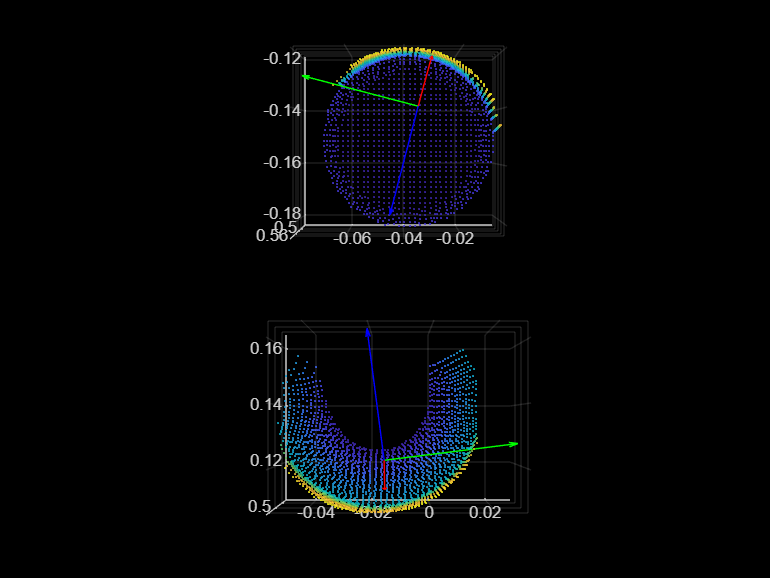

figure;

% For however many number of objects there are:
for idx = 1: numObjects

    % Retrieve PCA vectors (principal axes) for visualization
    U = scene_pca_vec{idx}.UVW(:,1);
    V = scene_pca_vec{idx}.UVW(:,2);
    W = scene_pca_vec{idx}.UVW(:,3);

    % Centroid of the current object
    center = scene_pca_vec{idx}.centroid;

    % Create subplot for current object
    nexttile;

    % Display the segmented object point cloud
    pcshow(ptCloud_vec{idx},'ViewPlane','XY');

    % Overlay principal axes (U:red, V:green, W:blue)
    hold on;
    quiver3(center(1), center(2), center(3), U(1), V(1), W(1), 'r');
    quiver3(center(1), center(2), center(3), U(2), V(2), W(2), 'g');
    quiver3(center(1), center(2), center(3), U(3), V(3), W(3), 'b');
    hold off;
    % red aroow is direction of greatest variance. If you look at object's
    % height then you can tell whether it is standing up or laying down
end

## Estimate object poses (betterObjectPoses)

gridDownsample = 0.002;
[xyz,theta,ptCloud_vec,scene_pca_vec] = betterObjectPoses(ptCloud, rgbImage, bboxes, gridDownsample, nonPlaneMask);

Error using images.geotrans.internal.rigidtform3dImpl (line 47)
Transformation matrix must be (d+1)-by-(d+1) or d-by-(d+1), where d is the dimensionality of the transformation.

Error in rigidtform3d (line 8)
            self = self@images.geotrans.internal.rigidtform3dImpl(varargin{:});

Error in <a href="matla